img = imread("Surtr.jpeg")

img = 500×888×3 uint8 数组
img(:,:,1) =

    44    45    46    46    45    46    46    47    48    48    48    48    49    49    49    49    49    49    49    49    49    49    50    50    49    49    49    50    51    53    54    55    54    54    55    55    55    55    56    56    59    59    59    59    59    59    59    59    59    60    60    61    61    62    62    62    62    63    64    64    63    62    62    62    62    62    62    63    63    63    64    64    63    63    64    64    63    64    65    65    68    67    70    70    68    69    72    72    73    73    74    74    74    74    74    74    72    72    70    70    70    70    69    69    71    70    70    70    71    72    72    72    71    72    72    73    74    74    74    74    76    76    76    76    77    77    77    77    77    77    78    78    78    79    80    82    81    82    83    84    84    83    84    84    85    84    84    84    85    86    88    89    90    91    93    94    95    95    95    95 

img = double(rgb2gray(img))

img =     47    48    49    49    48    49    49    50    51    51    51    51    52    52    52    52    52    52    52    52    52    52    53    53    52    52    52    53    54    56    57    58    57    57    58    58    58    58    59    59    62    62    62    62    62    62    62    62    62    63
    47    48    49    49    49    49    50    50    51    51    51    51    52    52    52    52    52    52    52    52    52    52    52    53    53    53    53    54    55    56    57    57    57    57    58    58    58    59    59    59    61    62    62    62    62    62    62    62    63    63
    47    48    49    49    49    49    50    50    51    51    51    51    52    52    52    52    52    52    52    52    52    52    52    52    53    53    54    54    55    56    57    58    58    58    58    59    59    60    60    60    61    61    62    62    62    62    62    62    63    63
    47    48    49    49    49    49    50    50    51    51    51    51    52    52    52 

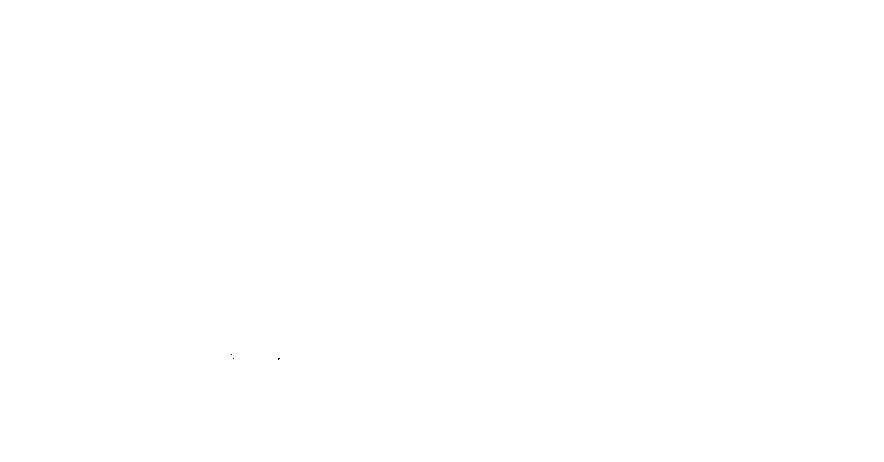

imshow(img)

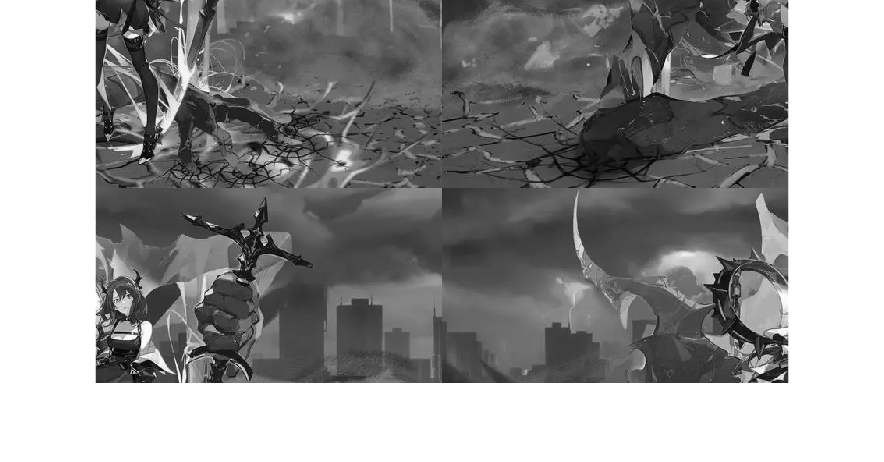

% 直接进行傅立叶变换
f1 = fftshift(img);
imshow(abs(f1),[])

f2 = real(ifftshift(f1));
imshow(f2)

%% 出现了混叠现象


PQ = paddedsize(size(img))

PQ =         1000        1776


[m1,n1] = size(img)

m1 = 500

n1 = 888

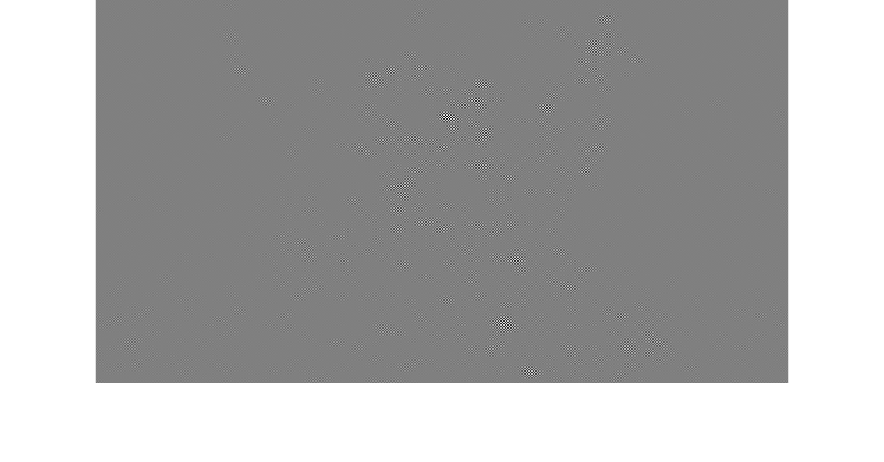

H = fspecial('gaussian',[m1,n1],20);
F = fft2(img);
G = H.*F;
g = real(ifft2(G));
imshow(g,[])


F = fft2(img,PQ(1),PQ(2));
H = fspecial('gaussian',[PQ(1),PQ(2)],10)

H =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

H = fftshift(H)

H =     0.0016    0.0016    0.0015    0.0015    0.0014    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0008    0.0007    0.0006    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0016    0.0016    0.0015    0.0015    0.0014    0.0014    0.0013    0.0012    0.0011    0.0010    0.0009    0.0008    0.0007    0.0006    0.0006    0.0005    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

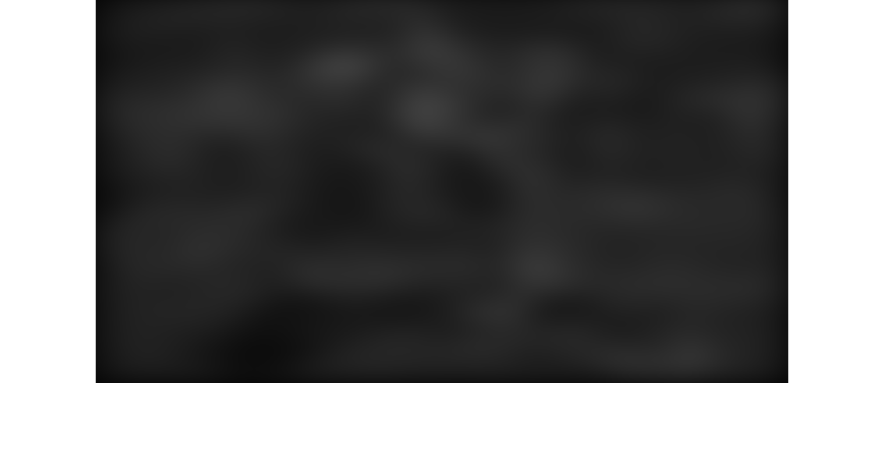

G = H.*F;
g = real(ifft2(G));
g = g(1 : size(img, 1), 1 : size(img, 2));
imshow(g)


h = fspecial('gaussian',[m1,n1],20);
gs = imfilter(double(img), h)

gs =    15.7127   16.3581   17.0052   17.6526   18.2991   18.9433   19.5840   20.2199   20.8499   21.4729   22.0876   22.6933   23.2888   23.8734   24.4462   25.0065   25.5538   26.0875   26.6070   27.1121   27.6023   28.0775   28.5376   28.9823   29.4118   29.8260   30.2250   30.6091   30.9783   31.3331   31.6736   32.0002   32.3134   32.6134   32.9007   33.1759   33.4392   33.6914   33.9328   34.1639   34.3853   34.5975   34.8011   34.9965   35.1842   35.3649   35.5391   35.7071   35.8696   36.0271
   16.3666   17.0384   17.7120   18.3859   19.0588   19.7293   20.3961   21.0579   21.7135   22.3617   23.0013   23.6314   24.2509   24.8589   25.4547   26.0375   26.6066   27.1615   27.7017   28.2268   28.7364   29.2304   29.7085   30.1706   30.6169   31.0472   31.4617   31.8607   32.2442   32.6126   32.9661   33.3053   33.6303   33.9417   34.2399   34.5254   34.7987   35.0603   35.3106   35.5504   35.7800   36.0001   36.2111   36.4137   36.6084   36.7957   36.9762   37.1503   37.3188   3

imshow(gs)


PQ = paddedsize(size(img))

PQ =         1000        1776


H = freqz2(h,PQ(1),PQ(2));
H1 = ifftshift(H);
gf = dftfilt(img, H1)

gf =    15.7127   16.3581   17.0052   17.6526   18.2991   18.9433   19.5840   20.2199   20.8499   21.4729   22.0876   22.6933   23.2888   23.8734   24.4462   25.0065   25.5538   26.0875   26.6070   27.1121   27.6023   28.0775   28.5376   28.9823   29.4118   29.8260   30.2250   30.6091   30.9783   31.3331   31.6736   32.0002   32.3134   32.6134   32.9007   33.1759   33.4392   33.6914   33.9328   34.1639   34.3853   34.5975   34.8011   34.9965   35.1842   35.3649   35.5391   35.7071   35.8696   36.0271
   16.3666   17.0384   17.7120   18.3859   19.0588   19.7293   20.3961   21.0579   21.7135   22.3617   23.0013   23.6314   24.2509   24.8589   25.4547   26.0375   26.6066   27.1615   27.7017   28.2268   28.7364   29.2304   29.7085   30.1706   30.6169   31.0472   31.4617   31.8607   32.2442   32.6126   32.9661   33.3053   33.6303   33.9417   34.2399   34.5254   34.7987   35.0603   35.3106   35.5504   35.7800   36.0001   36.2111   36.4137   36.6084   36.7957   36.9762   37.1503   37.3188   3

imshow(gf)

max(abs(gs-gf))

ans = 1.0e-05 *

    0.0981    0.0732    0.0545    0.0405    0.0300    0.0222    0.0164    0.0121    0.0088    0.0065    0.0047    0.0034    0.0025    0.0018    0.0013    0.0009    0.0007    0.0005    0.0004    0.0003    0.0002    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


function PQ = paddedsize(AB, CD, PARAM)
% 计算填充尺寸以供基于FFT的滤波器
% PQ = PADDEDSIZE(AB),AB = [A B], PQ = 2 * AB
%
% PQ = PADDEDSIZE(AB, 'PWR2')， PQ（1） = PQ（2） = 2 ^ nextpow2(2 * m), m =
% MAX(AB).
% 
% PQ = PADDEDSIZE(AB, CD)，AB = [A B], CD = [C D]
%
%  PQ = PADDEDSIZE(AB, CD, 'PWR2')， PQ（1） = PQ（2） = 2 ^ nextpow2(2 * m), m =
% MAX([AB CD]).

if nargin == 1
    PQ = 2 * AB;
elseif nargin == 2 & ~ischar(CD)
    PQ = AB + CD -1;
    PQ = 2 * ceil(PQ / 2);  % ceil（N）返回比N大的最小整数，为了避免出现奇数，因为处理偶数数组快
elseif nargin == 2
    m = max(AB);
    P = 2 ^ nextpow2(2 * m);  % nextpow2（N）返回第一个P，使得2. ^ P> = abs（N）。 
    % 对于FFT运算，找到最接近两个序列长度的2 的幂次方通常很有用。
    PQ = [P, P];
elseif nargin == 3
    m = max([AB CD]);
    P = 2 ^ nextpow2(2 * m);
    PQ = [P, P];
else
    error('Wrong number of input')
end
end


function g = dftfilt(f, H)
% DFTFILT performs frequency domain filtering.
%   G = DFTFILT(F, H) filters F in the frequency domain using the filter
%   transfer function H. The output, G, is the filtered image, which has
%   the same size as F. DFTFILT automatically pads F to be the same size as
%   H. Function PADEDESIZE can be used to determine an appropriate size
%   for H.
%   G = DFTFILT（F，H）使用滤波器传递函数H在频域中对输入图像F滤波。 输出G是滤波后的图像，
%   其大小与F相同。DFTFILT自动将F填充到与H相同的大小 ，PADEDESIZE函数可用于确定H的合适大小。
%
%   DFTFILT assumes that F is real and that H is a real, uncentered,
%   circularly-symmetric filter function.
%   DFTFILT假设F是实数，H是实数，未中心，循环对称的滤波函数。

% Obtain the FFT of the padded input.
% 获取填充之后的FFT变换
F = fft2(f, size(H, 1), size(H, 2));
% Perform filtering
% 滤波
g = real(ifft2(H .* F));
% Crop to orihinal size
% 剪切到原始尺寸
g = g(1 : size(f, 1), 1 : size(f, 2));
end